
Single objective optimization:
18 Variables
10 Integer variables
2 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1             1000       2.188e+06       5.157e+06        0
    2             1495       2.188e+06       4.681e+06        1
    3             1990       2.188e+06       4.461e+06        2
    4             2485       2.164e+06       4.305e+06        0
    5             2980       1.992e+06       3.953e+06        0
    6             3475       1.992e+06       3.631e+06        1
    7             3970       1.983e+06        3.31e+06        0
    8             4465       1.882e+06       3.163e+06        0
    9             4960       1.793e+06       2.933e+06        0
   10             5455 

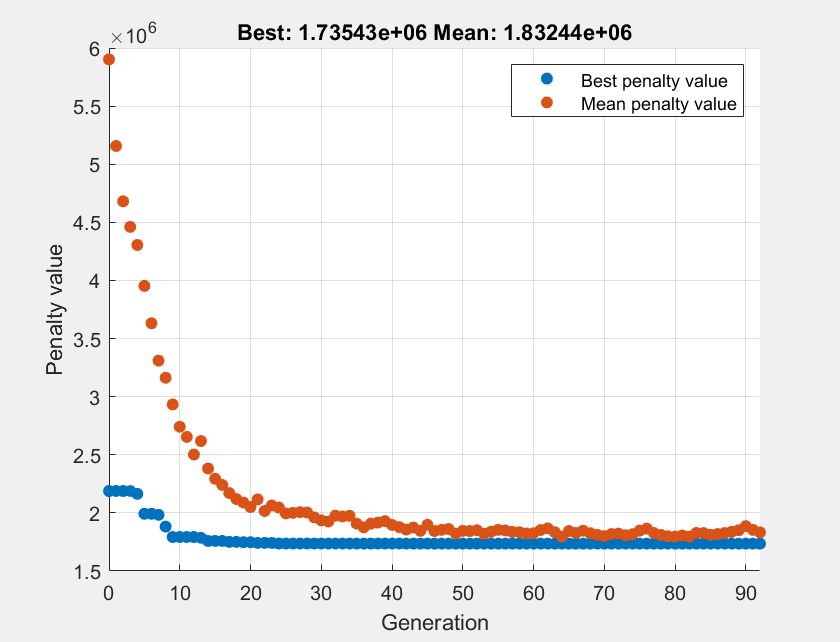

nvars = 18;
intcon = [1, 3, 8, 9, 10, 11, 15, 16, 17, 18];

lb = [0, 1, 1, 0, 30, 1.5e5, 0, 0, 0, 0, 0, 0.02, 0.02, 0.02, 1, 30, 0, 300];
ub = [1, 10, 10, 1, 45, 1.2e6, 60, 1, 1, 2, 2, 0.10, 0.10, 0.10, 3, 50, 1, 600];

options = optimoptions('ga', ...
    'Display', 'iter', ...
    'MaxGenerations', 300, ...
    'PopulationSize', 500, ...
    'PlotFcn', @gaplotbestf);

[x_opt, fval] = ga(@CombinedObjective, nvars, [], [], [], [], lb, ub, @Business_constraints, intcon, options);


fprintf("\n========== Final Decision Summary ==========\n");


========== Final Decision Summary ==========


[~, net_profit_total] = CombinedObjective(x_opt);
% Business Strategy
fprintf("\n--- Business Strategy ---\n");


--- Business Strategy ---


if x_opt(1), disp("Lobster fishing is ACTIVE"); else, disp("Lobster fishing is INACTIVE"); end

Lobster fishing is ACTIVE


if x_opt(4), disp("Cod/Shellfish fishing is ACTIVE"); else, disp("Cod/Shellfish fishing is INACTIVE"); end

Cod/Shellfish fishing is ACTIVE


if x_opt(9)
    fprintf("Boat will be rented for %d days\n", x_opt(8));
else
    disp("Boat rental is INACTIVE");
end

Boat will be rented for 1 days


if x_opt(10)
    disp("Sales strategy: Direct-to-Customer (higher revenue, labor cost applied)");
else
    disp("Sales strategy: Wholesale (lower revenue, no labor cost)");
end

Sales strategy: Direct-to-Customer (higher revenue, labor cost applied)


tier_labels = ["Low", "Medium", "High"];
fprintf("Lobster License Tier: %s\n", tier_labels(x_opt(11) + 1));

Lobster License Tier: High



% Boat Selection
fprintf("\n--- Boat Selection ---\n");


--- Boat Selection ---


hull_types = ["Planar", "Lobster Boat", "Downeast"];
fprintf("Hull Type: %s\n", hull_types(x_opt(15)));

Hull Type: Downeast


fprintf("Hull Length: %.1f ft\n", x_opt(16));

Hull Length: 50.0 ft


if x_opt(17) == 1
    engine_type_str = "Gasoline";
else
    engine_type_str = "Diesel";
end
fprintf("Engine Type: %s\n", engine_type_str);

Engine Type: Diesel



fprintf("Engine Horsepower: %.0f HP\n", x_opt(18));

Engine Horsepower: 300 HP



% Fishing Strategy
fprintf("\n--- Fishing Strategy ---\n");


--- Fishing Strategy ---


lobster_season = [127, 273]; cod_season = [244, 304]; scallop_season = [152, 273];
lobster_days = lobster_season(2) - lobster_season(1) + 1;
cod_days = cod_season(2) - cod_season(1) + 1;
scallop_days = scallop_season(2) - scallop_season(1) + 1;

if x_opt(1)
    fprintf("Lobster: ACTIVE (%d days/year), Crew Cut = %.2f%%\n", lobster_days, 100 * x_opt(12));
else
    fprintf("Lobster: INACTIVE\n");
end

Lobster: ACTIVE (147 days/year), Crew Cut = 10.00%


if x_opt(4)
    fprintf("Cod: ACTIVE (%d days/year), Crew Cut = %.2f%%\n", cod_days, 100 * x_opt(13));
else
    fprintf("Cod: INACTIVE\n");
end

Cod: ACTIVE (61 days/year), Crew Cut = 10.00%


if x_opt(4)
    fprintf("Shellfish: ACTIVE (%d days/year), Crew Cut = %.2f%%\n", scallop_days, 100 * x_opt(14));
else
    fprintf("Shellfish: INACTIVE\n");
end

Shellfish: ACTIVE (122 days/year), Crew Cut = 10.00%



% Get fishing revenue for breakdown output
[~, fishing_revenue] = FishingObjective(x_opt(12:14));

% Business breakdown with passed-in revenue
[~, net_profit, revenue_breakdown, cost_breakdown] = Business(x_opt(1:11), fishing_revenue);
fprintf("\n--- Revenue Breakdown ---\n");


--- Revenue Breakdown ---


fprintf("Lobster Revenue: $%.2f\n", revenue_breakdown.Lobster);

Lobster Revenue: $638400.00


fprintf("Fish Revenue:    $%.2f\n", revenue_breakdown.Fish);

Fish Revenue:    $80573.24


fprintf("Rental Revenue:  $%.2f\n", revenue_breakdown.Rental);

Rental Revenue:  $900.00



fprintf("\n--- Cost Breakdown ---\n");


--- Cost Breakdown ---


fprintf("Maintenance Cost: $%.2f\n", cost_breakdown.Maintenance);

Maintenance Cost: $5000.00


fprintf("License Cost:     $%.2f\n", cost_breakdown.Licenses);

License Cost:     $77000.00


fprintf("Loan Cost:        $%.2f\n", cost_breakdown.Loan);

Loan Cost:        $162000.00


fprintf("Labor Cost:       $%.2f\n", cost_breakdown.Labor);

Labor Cost:       $76800.00




total_revenue = revenue_breakdown.Lobster + revenue_breakdown.Fish + revenue_breakdown.Rental;
total_costs   = cost_breakdown.Maintenance + cost_breakdown.Licenses + cost_breakdown.Loan + cost_breakdown.Labor;
crew_pay      = 2 * 0.10 * (revenue_breakdown.Lobster + revenue_breakdown.Fish); % 2 crew at 20% cut

true_net_profit = total_revenue - total_costs - crew_pay;

fprintf("\n=== Manually Calculated Net Profit ===\n");


=== Manually Calculated Net Profit ===


fprintf("Total Revenue:       $%.2f\n", total_revenue);

Total Revenue:       $719873.24


fprintf("Total Costs:         $%.2f\n", total_costs);

Total Costs:         $320800.00


fprintf("Crew Pay (2 x 10%%):  $%.2f\n", crew_pay);

Crew Pay (2 x 10%):  $143794.65


fprintf("Net Profit (True):   $%.2f\n", true_net_profit);

Net Profit (True):   $255278.59
